clc;
clear all;
close all;

folderName = "../Processed_Audio_"

folderName = "../Processed_Audio_"

normalizeMethod = "range"

normalizeMethod = "range"

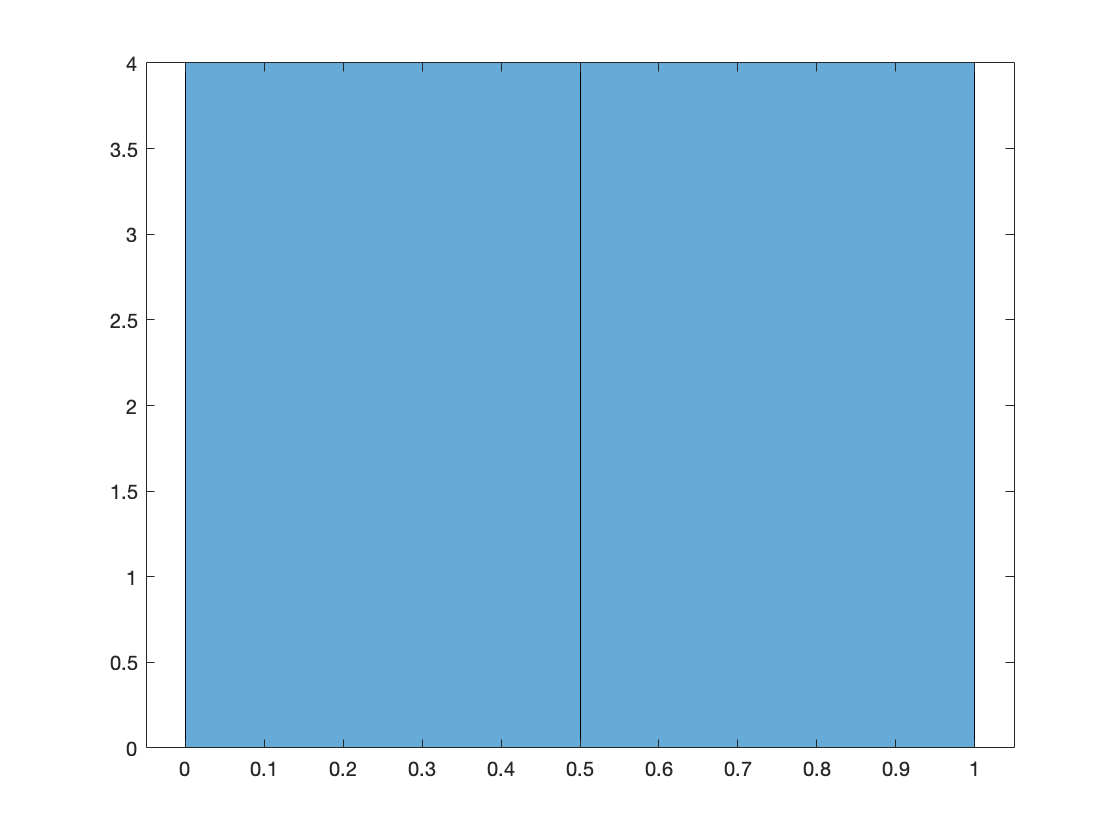

youtubeFeatures = readtable('training-data-label.csv', 'VariableNamingRule','preserve');
labelValues = youtubeFeatures(:,{'Title' 'Like:Dislike'});
labelValues.("Like:Dislike")= normalize (labelValues.("Like:Dislike"), normalizeMethod);
%Checking to verify the median value
histogram(labelValues.("Like:Dislike"));

%Threshold is needed to convert from a regression problem to a catergorical
%one
threshold= median( labelValues.("Like:Dislike") , 'all' );
tempCat = any(labelValues.("Like:Dislike") >= threshold,2);
labelValues.Catergories = categorical(tempCat);
labelValues.Title = string(labelValues.Title)

labelValues = 8×3 table
                                             Title                                             Like:Dislike    Catergories
    _______________________________________________________________________________________    ____________    ___________

    "Preventing COVID-19 in your workplace or while teleworking"                                  0.15676         false   
    "If you are going out…"                                                                       0.12985         false   
    "What can people do to protect themselves and others from getting the new coronavirus?"       0.60709         true    
    "Can masks protect against the new coronavirus infection?"                                   0.037902         false   
    "Why is it recommended to avoid close contact with anyone who has fever and cough?"                 0         false   
    "How the

folder = fullfile(matlabroot,'toolbox','audio','samples');
ads = audioDatastore(folderName,"IncludeSubfolders",true, "LabelSource","foldernames");

% labelvals = table2array(labelValues(:,"Catergories"))

labelvals = [0 0 1 1 1 0 0 1 1 1 1 1 1 1 0 0]

labelvals =      0     0     1     1     1     0     0     1     1     1     1     1     1     1     0     0



ads.Labels = categorical(labelvals);

Error using audioDatastore/subsasgn (line 381)
The length of Labels must be equal to the number of files in the datastore.